%{
    README
    Author: Aaron P. Ledray
    Date: 20240310
    Description: Script to check channels, check scan files, and sum data
    for X-ray experiments at SSRL, beamline 4-3 using the 7-element
    detector.

    Inspiration came from EXAFSPAK by Dr. G. N. George (2001).

    Instructions: Run section by section! Read the description first.

    I recommend keeping the script in the directory that is directly above
    the sample directories. For example:

    Directory for experiment trip --- Contains pre-processing script
    ---> sub directory for each experiment sample, each containing only
    scan files.

    ( Just read the instructions ) 




    20240310: Comments by CVS - future recommendations:

V2:

Notes: I0 is unique for each scan file, so you need to divide SCA-sum by I0
FIRST before summing across files.

It's on the SUMMAITON steps in which you want to divide by I0!!!

For each unique scan, I1 and I2 also contains the calibrant data... "that
contains the metal foil, the I2 thing"

%}


% Section 1: Selecting the correct sub-directory

% Direct the script to a working directory that contains ONLY different
% scans from a specific sample's batch. The following section navigates the
% script to the appropraite directory.

% Get a list of all subdirectories
subdirs = dir;
subdirs(~[subdirs.isdir]) = [];  % remove non-directories
subdirs = subdirs(3:end);  % remove '.' and '..'

% Display the list of subdirectories to the user
fprintf('Subdirectories:\n');
for i = 1:length(subdirs)
    fprintf('%d: %s\n', i, subdirs(i).name);
end

% Prompt the user to select a subdirectory
selected = input('Please enter the number of the subdirectory you want to use: ');

% Change the working directory to the selected subdirectory
cd(subdirs(selected).name);



% Section 2: Plotting individual channels for individual files 

% This section will iterate through the working directry and either 1) for
% all files will one-at-a-time plot SCA channels or 2) for specific
% channels. Included is the option to plot individual channels.

% Get a list of all files in the current directory
files = dir;
files = files(~[files.isdir]);  % remove directories

% Display the list of files to the user
fprintf('Files:\n');

Files:


for i = 1:length(files)
    fprintf('%d: %s\n', i, files(i).name);
end

1: Ni2_ME_EXAFS_1_002_A.001
2: Ni2_ME_EXAFS_1_003_A.001
3: Ni2_ME_EXAFS_1_004_A.001
4: Ni2_ME_EXAFS_1_005_A.001


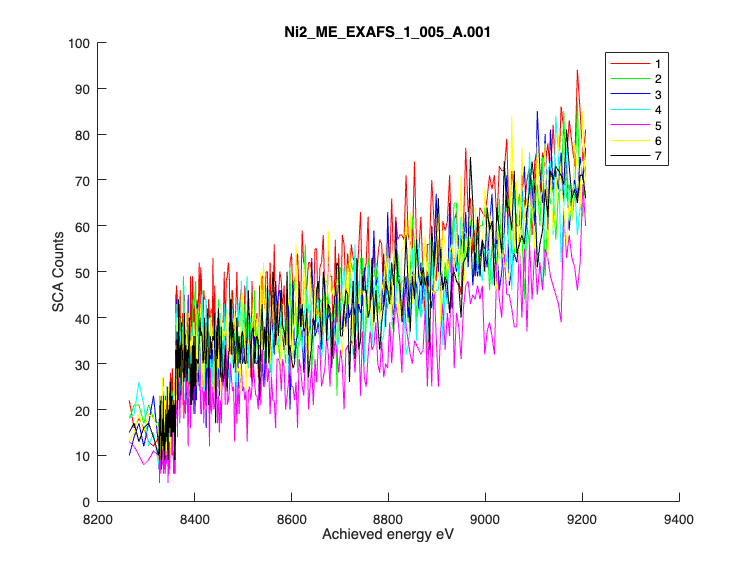


% Prompt the user to select a file or go through all files
choice = input('Would you like to: \n1) Go through all the files one-at-a-time \n2) Look at a specific file \nEnter your choice (1 or 2): ');

if choice == 2
    % If the user chose to look at a specific file, prompt them to select a file
    selected = input('Please enter the number of the file you want to use: ');
    % Set the file to the selected file
    file = files(selected).name;
    
    % Import the selected file as a numeric matrix
    data = importData(file);
    
    % Prompt the user to select the SCA channels to plot
    channels = input(['Which SCA channels would you like to plot for file ', file, '? Enter a vector of channels (1-7) or "all" in quotaiton marks. For example, [1 2 3 4 7] for channels 1 through 4 and 7: ']);

    % If the user entered 'all', set channels to 1 through 7
    if strcmpi(channels, 'all')
        channels = 1:7;
    end

    % Plot the data
    plotData(data, channels, file);
else
    % If the user chose to go through all files, loop through all files
    for i = 1:length(files)
        % Set the file to the current file
        file = files(i).name;
        
        % Import the current file as a numeric matrix
        data = importData(file);
        
        % Prompt the user to select the SCA channels to plot
        channels = input(['Which SCA channels would you like to plot for file ', file, '? Enter a vector of channels (1-7) or "all" in quotation marks. For example, [1 2 3 4 5 7] for channels 1 through 5 and 7: ']);

        % If the user entered 'all', set channels to 1 through 7
        if strcmpi(channels, 'all')
            channels = 1:7;
        end

        % Plot the data
        plotData(data, channels, file);
        
        % Pause execution to display the plot
        fprintf('Press any key to continue to the next file...\n');
        pause;
    end
end

% Section 4: Channel Sum and Plotting

% This section will (for each individual file) sum all channels except
% those excluded and plot the results, either for a 1) specific file or 2) for
% all of them.


% Display the list of files to the user
fprintf('Files:\n');

Files:


for i = 1:length(files)
    fprintf('%d: %s\n', i, files(i).name);
end

1: Ni2_ME_EXAFS_1_002_A.001
2: Ni2_ME_EXAFS_1_003_A.001
3: Ni2_ME_EXAFS_1_004_A.001
4: Ni2_ME_EXAFS_1_005_A.001


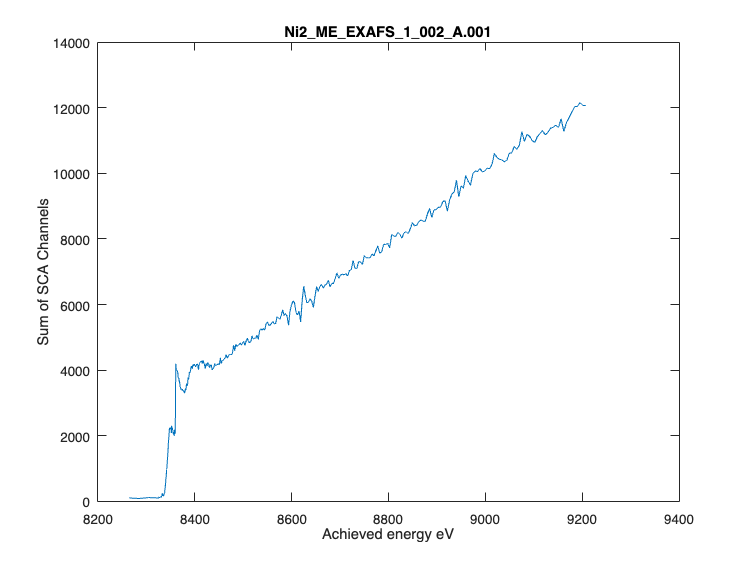

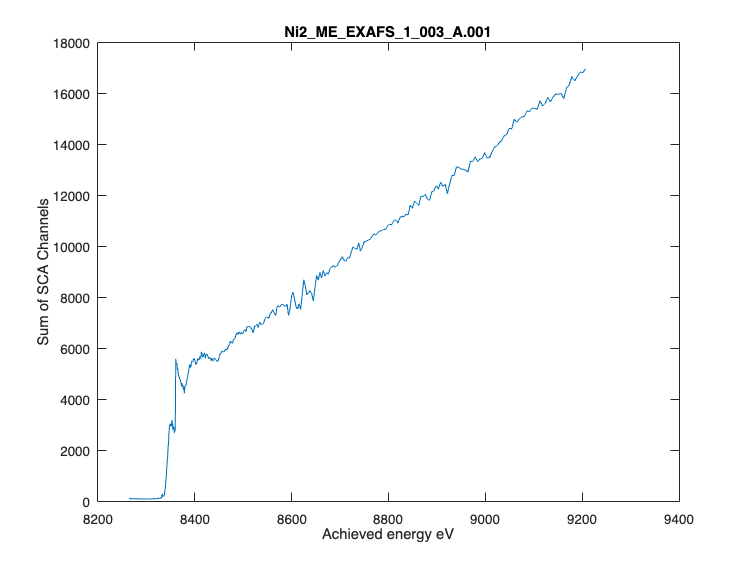

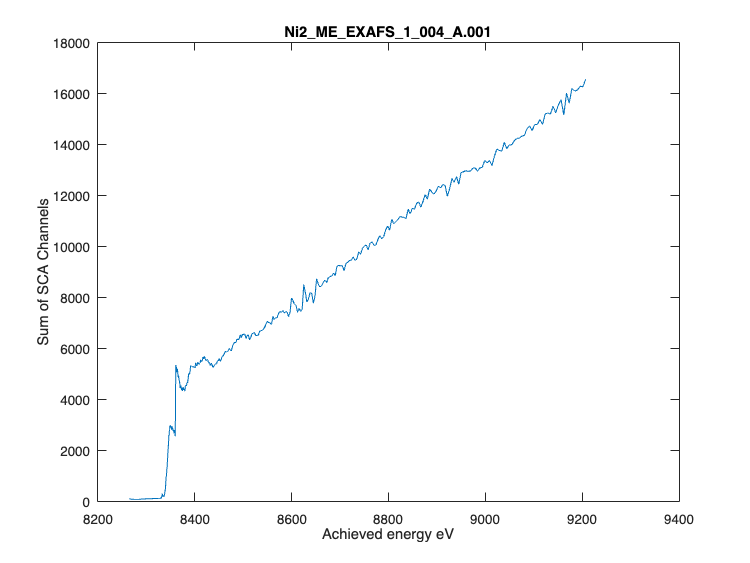

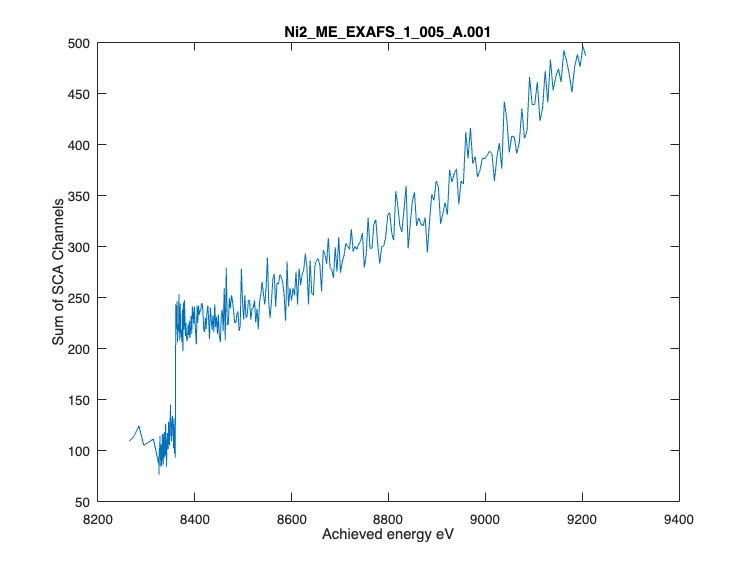


% Prompt the user to select the channels to exclude from the sum
exclude = input('Which channels would you like to NOT INCLUDE in the sum? Enter a vector of channels (1-7) or "none" in quotation marks. For example, [1] or [1 2 3] for channels 1 through 3: ', 's');

% If the user entered 'none', set exclude to an empty array
if strcmpi(exclude, 'none')
    exclude = [];
else
    % Convert the user input to a numeric array
    exclude = str2num(exclude);  %#ok<ST2NM>
end

% Get a list of all channels
allChannels = 1:7;

% Remove the excluded channels from the list
channelsToSum = setdiff(allChannels, exclude);


% Loop through all files
for i = 1:length(files)
    % Set the file to the current file
    file = files(i).name;
    
    % Import the current file as a numeric matrix
    data = importData(file);
    
    % Sum the selected channels
    sumData = sum(data(:, channelsToSum+10), 2);
    
    % Plot the sum data
    figure;
    plot(data(:, 4), sumData);
    
    % Add labels to the plot
    xlabel('Achieved energy eV');
    ylabel('Sum of SCA Channels');
    title(file, 'Interpreter', 'none');
end


% Section 5: Sum of Sums and Plotting

% This section will add the sums across all relevant files after prompting
% you which files to exclude.

% Check if 'exclude' variable exists
if exist('exclude', 'var')
    % Confirm the channels to exclude
    if isempty(exclude)
        confirm = input('You previously chose to exclude no channels. Would you like to continue with these exclusions? Enter "yes" or "no" in quotation marks: ', 's');
    else
        confirm = input(['You previously chose to exclude channels ' num2str(exclude) '. Would you like to continue with these exclusions? Enter "yes" or "no" in quotation marks: '], 's');
    end
    if strcmpi(confirm, 'no')
        % Prompt the user to select the channels to exclude from the sum
        exclude = input('Which channels would you like to NOT INCLUDE in the sum? Enter a vector of channels (1-7) or "none" in quotation marks. For example, [1] or [1 2 3] for channels 1 through 3: ', 's');
        if strcmpi(exclude, 'none')
            exclude = [];
        else
            exclude = str2num(exclude);  %#ok<ST2NM>
        end
    end
else
    % If 'exclude' variable does not exist, prompt the user to select the channels to exclude
    exclude = input('Which channels would you like to NOT INCLUDE in the sum? Enter a vector of channels (1-7) or "none" in quotation marks. For example, [1] or [1 2 3] for channels 1 through 3: ', 's');
    if strcmpi(exclude, 'none')
        exclude = [];
    else
        exclude = str2num(exclude);  %#ok<ST2NM>
    end
end


% List all file names
files = dir;
files = files(~[files.isdir]);  % remove directories
fileNames = {files.name};


disp('The following files are available:');

The following files are available:


disp(fileNames);

    {'Ni2_ME_EXAFS_1_002_A.001'}    {'Ni2_ME_EXAFS_1_003_A.001'}    {'Ni2_ME_EXAFS_1_004_A.001'}    {'Ni2_ME_EXAFS_1_005_A.001'}







% Prompt the user to select the files to exclude from the sum
excludeFilesIndices = input('Which files would you like to NOT INCLUDE in the sum? Enter a vector of file indices or "none" in quotation marks. For example, [1] or [1 2 3] for files 1 through 3: ', 's');

if strcmpi(excludeFilesIndices, 'none')
    excludeFiles = {};
else
    excludeFilesIndices = str2num(excludeFilesIndices);  %#ok<ST2NM>
    excludeFiles = fileNames(excludeFilesIndices);
end



% Initialize the sum of sums
sumOfSums = zeros(size(data(:, channelsToSum+10)));

% Loop through all files
for i = 1:length(files)
    % Set the file to the current file
    file = files(i).name;
    
    % Skip the excluded files
    if ismember(file, excludeFiles)
        continue;
    end
    
    % Import the current file as a numeric matrix
    data = importData(file);
    
    % Sum the selected channels
    sumData = sum(data(:, channelsToSum+10), 2);
    
    % Add to the sum of sums
    sumOfSums = sumOfSums + sumData;
end

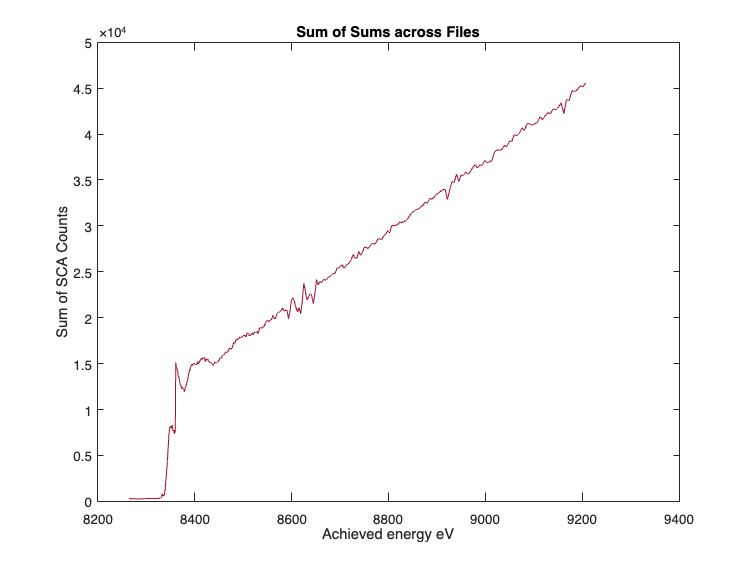


% Plot the sum of sums
figure;
plot(data(:, 4), sumOfSums);
xlabel('Achieved energy eV');
ylabel('Sum of SCA Counts');
title('Sum of Sums across Files', 'Interpreter', 'none');

function data = importData(file)
    % Import the file as a table
    T = readtable(file, 'FileType', 'text');
    
    % Convert rows 45 through end of the table to a cell array
    C = table2cell(T(45:end, :));
    
    % Split each string into individual numbers
    C = cellfun(@(x) strsplit(x, '  '), C, 'UniformOutput', false);
    
    % Convert the cell array to a numeric matrix
    data = cellfun(@(x) cellfun(@str2double, x), C, 'UniformOutput', false);
    data = cell2mat(data);
end

function plotData(data, channels, file)
    % Create a color map for the plot
    colors = ['r', 'g', 'b', 'c', 'm', 'y', 'k'];

    % Plot the selected channels
    figure;
    hold on;
    for i = channels
        plot(data(:, 4), data(:, i+10), 'Color', colors(i));
    end
    hold off;

    % Add labels to the plot
    xlabel('Achieved energy eV');
    ylabel('SCA Counts');
    legend(arrayfun(@num2str, channels, 'UniformOutput', false));
    title(file, 'Interpreter', 'none');
   
end